# UMAP paper code 1

## N sesion by sesion

dirs = ["../../../../../../../../../../../../../../home/bernardo/Desktop/Paper_sebas/Datos/All_Neurons", ...
    "../../../../../../../../../../../../../../home/bernardo/Documents/Datos_monos_32y33/RR032i_processed/All_Neurons"];
Nsesion = 10;
N_methods = zeros(Nsesion, 2);
Files = cell(1,2);

for d = 1:2
    cd(dirs(d));
    Files{d} = dir('*.*');
    DayOfN = [];
    for f = 1:length(Files{d})
        if length(Files{d}(f).name) > 3 && Files{d}(f).name(8) == "e" && str2num(Files{d}(f).name([2,3])) < 72
            DayOfN = [DayOfN, str2num(Files{d}(f).name([2,3]))];
        end
    end
    uniqueDays = unique(DayOfN);
    for day = 1:Nsesion
        N_methods(day,d) = sum(DayOfN == uniqueDays(day));
    end
end

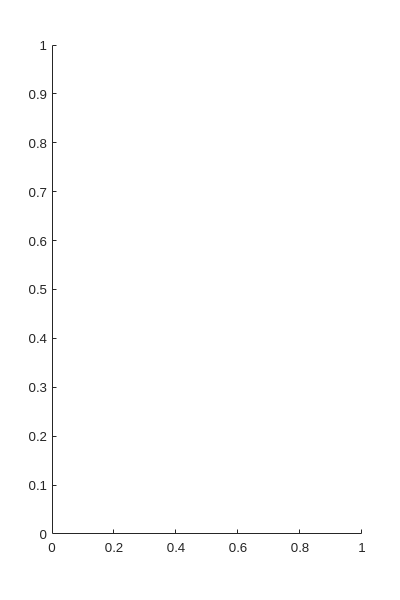

clf, hold off

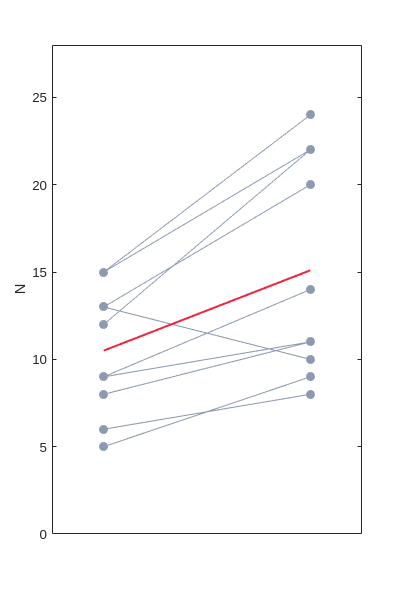

figure('Renderer', 'painters', 'Position', [10 10 400 600])
plot(N_methods.',Color="#8d99ae",Marker=".",MarkerSize=20)
hold on
plot(mean(N_methods),Color="#ef233c",LineWidth=1.5)
ylabel("N")
xlim([0.75,2.25])
ylim([0,28])
xticklabels([])
xticks([])
%saveas(gcf, "N_VPCi.svg")

[~,~,~,stats] = ttest(N_methods(:,1),N_methods(:,2));
Ttrue = stats.tstat

Ttrue = -3.7643


Tperm = zeros(1,1000);
Np = [N_methods(:,1),N_methods(:,2)];
for p = 1:1000
    Np = Np(randperm(length(Np)));
    [~,~,~,stats] = ttest(Np(1:10),N_methods(11:end));
    Tperm(p) = stats.tstat;
end

pvalue = sum(abs(Tperm) > abs(Ttrue))/1000

pvalue = 0.0030

## Information

### Import UMAP

N_UMAP = 151; %first 5 days, 60 neurons


### Import PCA-kmeans

%home/bernardo/Desktop/Paper_sebas/Datos/All_Neurons

N = 105; %number of neurons
P = 11; %number of psychometrics files

Psychos = cell(N,1);
Neurons = cell(N,1);

n = 1; p = 1;
Files=dir('*.*');
for f = 1:length(Files)
    if length(Files(f).name) > 3 && Files(f).name(8) == "e"
        Neurons{n} = readmatrix(Files(f).name);
        n = n + 1;
    elseif Files(f).name(1) == "p"
        Psychos{p} = readPsico(Files(f).name);
        p = p + 1;
    end
end

pi = AllPsico;

#### Remove misses and fix neurons VPCi 32

Neu = cell(N,1); Psyhit = cell(P+2,1);
for n = 1:N
    if n == 14 %fix warnings
        Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1 & Psychos{pi(n)}.Trial > 40, :);
        pi(n) = P + 1;

    elseif n == 64 || n == 65 %fix warnings
        Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1 & Psychos{pi(n)}.Trial > 20, :);
        pi(n) = P + 2;
    
    else
        try
            Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1, :); 
        catch
            n
        end
    end
end
Psyhit{P+1} = Psychos{2}(Psychos{2}.Hits == 1 & Psychos{2}.Trial > 40, :); 
Psyhit{P+2} = Psychos{8}(Psychos{8}.Hits == 1 & Psychos{8}.Trial > 20, :);

for p = 1:P
    Psyhit{p} = Psychos{p}(Psychos{p}.Hits == 1, :); 
end

#### Align times and remove missing trails neurons VPCi 32

err = zeros(6,1); 
i = 0;
for n = 1:N
    try
        Neu{n} = Neu{n}./30000 - Psyhit{pi(n)}.o3;
    catch
        i = i + 1;
        err(i) = n;
        n
    end
end

for n = 1:i
    Neu{err(n)} = zeros(length(Psyhit{pi(err(n))}.o3),1);
end


#### Frequency

mini = -7; pas = 0.02; maxi = 4; 
tv = mini:pas:maxi;
lentv = length(tv);
Fr = cell(N, 1);
for n = 1:N
    Fr{n} = freq(Neu{n}, pas, 0.2, mini, maxi);
end

meanClass = cell(N,1);
classes = [0., 0.;
           0., 0.006;
           0., 0.1;
           0., 0.5;
           0., 1.;
           0., 2.5;
           6., 0.;
           8., 0.;
           10., 0.;
           12., 0.;
           24., 0.];
C = 11; %number of classes

for n = 1:N
    meanClass{n} = zeros(C,lentv);
    for c = 1:C
        if c == 10
            meanClass{n}(c,:) = mean(Fr{n}((Psyhit{pi(n)}.AmpStim3 == classes(c,1) | Psyhit{pi(n)}.AmpStim3 == 16.) ...
                & Psyhit{pi(n)}.AudStim3 == classes(c,2), :), 1);
        elseif c == 11
            meanClass{n}(c,:) = mean(Fr{n}((Psyhit{pi(n)}.AmpStim3 == classes(c,1) | Psyhit{pi(n)}.AmpStim3 == 20.) ...
                & Psyhit{pi(n)}.AudStim3 == classes(c,2), :), 1);
        else
            meanClass{n}(c,:) = mean(Fr{n}(Psyhit{pi(n)}.AmpStim3 == classes(c,1) & Psyhit{pi(n)}.AudStim3 == classes(c,2), :), 1);
        end
    end
end

Vector form

meanClassvec = zeros(N,C,lentv);
    
for n = 1: N
    meanClassvec(n,:,:) = meanClass{n}(:,:);
end
%meanClassvec(isnan(meanClassvec))=0;

## Mutual Information

#### UMAP

IMr_UMAP = IM_UMAP - mean(IMp_UMAP,3);
IMr_UMAP(IMr_UMAP < 0) = 0;

figure('Renderer', 'painters', 'Position', [10 10 800 600])
clf, hold off
plot(tv(wind),mean(IM_UMAP))
hold on
plot(tv(wind),mean(IMr_UMAP))

Electrodes_UMAP = which_el(Files{2},N_UMAP);

tvw = tv(wind);
Nel = Electrodes_UMAP(end)

Nel = 58

IMel_UMAP = zeros(Nel,1);
for e = 1:Nel
    IMel_UMAP(e) = sum(mean(IMr_UMAP(Electrodes_UMAP == e,tvw > 0),2));
end

#### PCA k-means

i = tv(326); e = tv(526);
wind = tv >= i & tv <= e;
lenwin = sum(wind);
Ps = [1/3, 1/3, 1/3]; IM_PCA = zeros(N,lenwin);

for n = 1:N
    for t1 = 1: lenwin
        t = t1 + 325;
        ed = linspace(min(Fr{n}(:,t),[],"all"),max(Fr{n}(:,t),[],"all"),10);
        Pt = histcounts(Fr{n}(:,t),ed,"Normalization","probability");
        
        Psr1 = histcounts(Fr{n}(Psyhit{pi(n)}.AmpStim3 ~= 0. & Psyhit{pi(n)}.AudStim3 == 0.,t), ... 
            ed,"Normalization","probability");
        Psr2 = histcounts(Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 ~= 0.,t), ...
            ed,"Normalization","probability");
        Psr3 = histcounts(Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 == 0.,t), ...
            ed,"Normalization","probability");
        IM_PCA(n,t1) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan") + Ps(3)*sum(Psr3.*log2(Psr3./Pt),"omitnan");        
    end
end

#### Permutations

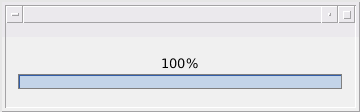

IMp_PCA = zeros(N,lenwin, 1000);

wb = waitbar(0);
for n = 1:N
    waitbar(n/N, wb, strcat(num2str(round(n/N*100,2)),"%"))
    for t1 = 1:lenwin
        t = t1 + 325;
        ed = linspace(min(Fr{n}(:,t),[],"all"),max(Fr{n}(:,t),[],"all"),10);
        Pt = histcounts(Fr{n}(:,t),ed,"Normalization","probability");
        Frp = Fr{n}(:,t);

        for p = 1:1000
        Frp = Frp(randperm(length(Frp)));

        Psr1 = histcounts(Frp(Psyhit{pi(n)}.AmpStim3 ~= 0. & Psyhit{pi(n)}.AudStim3 == 0.), ...
            ed,"Normalization","probability");
        Psr2 = histcounts(Frp(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 ~= 0.), ...
            ed,"Normalization","probability");
        Psr3 = histcounts(Frp(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 == 0.), ...
            ed,"Normalization","probability");
        IMp_PCA(n,t1,p) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan") + Ps(3)*sum(Psr3.*log2(Psr3./Pt),"omitnan");
        end
    end
end

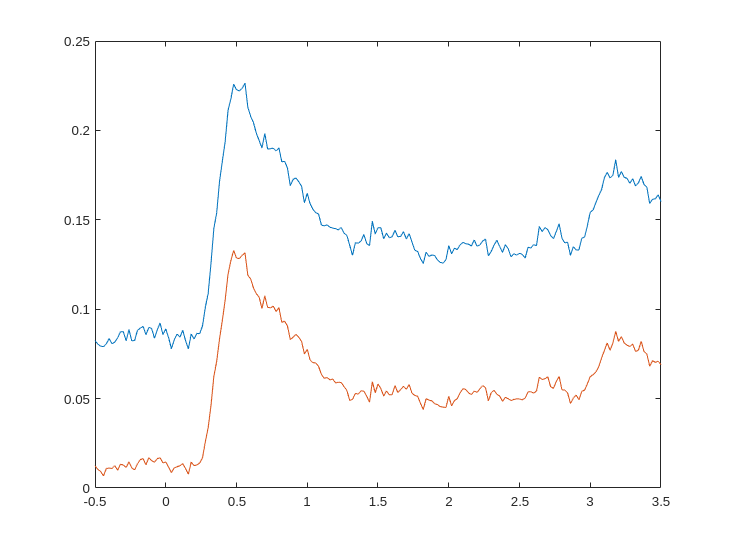

Nel = 53

IMr_PCA = IM_PCA - mean(IMp_PCA,3);
IMr_PCA(IMr_PCA < 0) = 0;

figure('Renderer', 'painters', 'Position', [10 10 800 600])
clf, hold off
plot(tv(wind),mean(IM_PCA))
hold on
plot(tv(wind),mean(IMr_PCA))

Missing electrodes 

ename = zeros(60,2);
for d = 1:2
    e = 2;
    for f = 1:length(Files{d})
        if length(Files{d}(f).name) > 9 && Files{d}(f).name(8) == "e" && str2num(Files{d}(f).name([2,3])) < 72
            if str2num(Files{d}(f).name([2,3,7,9])) ~= ename(e-1,d)
                ename(e,d) = str2num(Files{d}(f).name([2,3,7,9]));
                e = e + 1;
            end
        end
    end
end

missing_electrodes = ename(~ismember(ename(:,2),ename(:,1)),2)

missing_electrodes =         6031
        6421
        6725
        6927
        7124


me_i = find(ismember(ename(:,2),ename(:,1)) == 0) - 1;

Electrodes_PCA = which_el(Files{1},N_PCA);
for e = 1:length(me_i)
    Electrodes_PCA(Electrodes_PCA >= me_i(e)) = Electrodes_PCA(Electrodes_PCA >= me_i(e)) + 1;
end

IMel_PCA = zeros(Nel,1);
for e = 1:Nel
    IMel_PCA(e) = sum(mean(IMr_PCA(Electrodes_PCA == e,tvw > 0),2));
end

There is an error in electrode 20 in indexing in UMAP, removing this electrode for ploting 

IMel_PCA(20) = nan;
IMel_UMAP(20) = nan;

Ploting

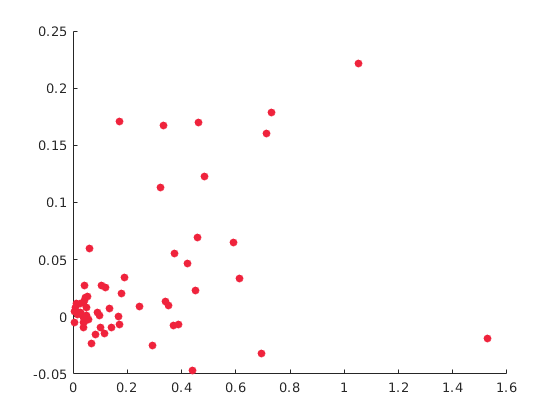

clf, hold off
scatter(IMel_UMAP + IMel_PCA,IMel_UMAP - IMel_PCA,MarkerFaceColor="#ef233c",MarkerEdgeColor="none")
hold on
%plot([0,0.7],[0,0.7],Color="r",LineStyle="--")
%xlabel("IM_ePCA")
%ylabel("IM_eUMAP")
%saveas(gcf, "IMe_VPCi2.svg")

[~,~,~,stats] = ttest(IMel_PCA,IMel_UMAP);
Ttrue_im = stats.tstat

Ttrue_im = -3.7597


Tperm = zeros(1,1000);
Np = [N_methods(:,1),N_methods(:,2)];
for p = 1:1000
    Np = Np(randperm(length(Np)));
    [~,~,~,stats] = ttest(Np(1:10),N_methods(11:end));
    Tperm(p) = stats.tstat;
end

pvalue_im = sum(abs(Tperm) > abs(Ttrue_im))/1000

pvalue_im = 0.0030

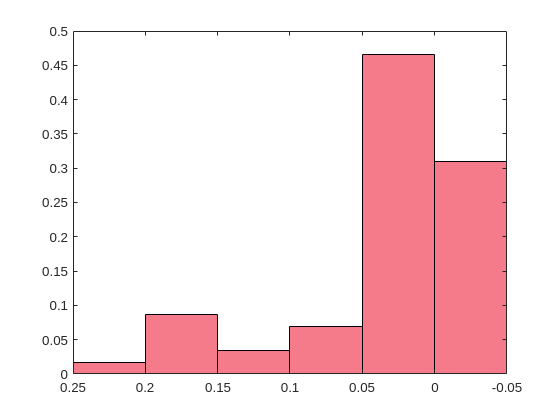

%IMangle = atan(IMel_UMAP./IMel_PCA).*180./3.141592;
clf, hold off
histogram(IMel_UMAP - IMel_PCA,FaceColor="#ef233c",Normalization="probability",BinEdges=-0.05:0.05:0.25)
hold on
xlim([-0.05,0.25])
set(gca, 'XDir','reverse')
saveas(gcf, "IMetheta_VPCi.svg")

## Firing rate Fig. 6

"e2neuron_1.csv" and "e2neuron_2.csv"

Frg = cell(3,1);
sigma = 0.4;
Frg{1} = convo(Neu_UMAP{22}, pas, sigma, mini, maxi,2);
Frg{2} = convo(Neu_UMAP{23}, pas, sigma, mini, maxi,2);
Frg{3} = convo(Neu_UMAP{23}, pas, sigma, mini, maxi,2);
Psyhitg = Psyhit_UMAP{pi_UMAP(22)};

meanClassg = cell(3,1);

for n = 1:3
    meanClassg{n} = zeros(C,lentv);
    for c = 1:C
        meanClassg{n}(c,:) = mean(Frg{n}(Psyhitg.AmpStim3 == classes(c,1) & Psyhitg.AudStim3 == classes(c,2), :), 1);
    end
end

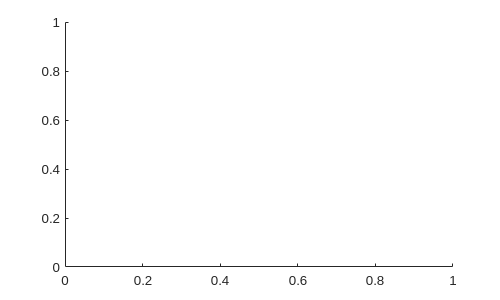

clf, hold off

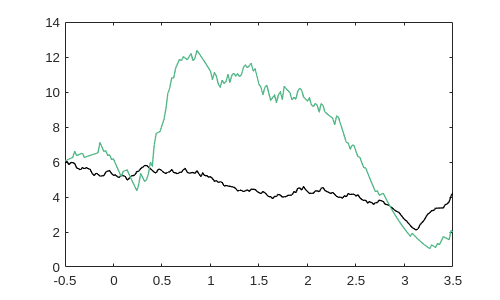

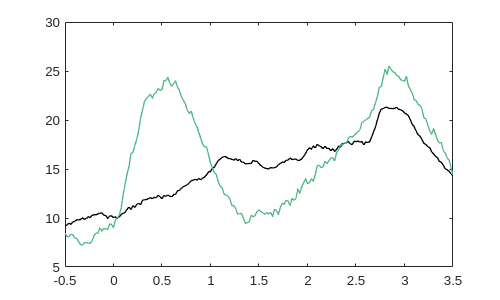

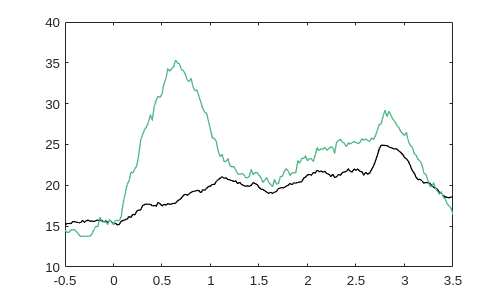

fignames = {'Fr1.svg','Fr2.svg','Fr3.svg'};
for n = 1:3
    figure(n)
    figure('Renderer', 'painters', 'Position', [10 10 500 300])
    clf, hold off
    plot(tv(wind),meanClassg{n}(1,wind),color="k",LineWidth=1)
    hold on
    plot(tv(wind),meanClassg{n}(end,wind),color="#52b788",LineWidth=1)
    xlim([-0.5,3.5])
    %title(fignames{n})
    saveas(gcf, fignames{n})
end

## Probability of f1 Fig. 4

This code complements the code of "fig4"

f1 score distribution calculation

ename_UMAP = zeros(310,1);

a = 1;
for f = 1:length(Files{2})
    if length(Files{2}(f).name) > 9 && Files{2}(f).name(8) == "e"
        ename_UMAP(a) = str2num(Files{2}(f).name([2,3,7,9]));
        a = a + 1;

    end
end

Diff_neu = cell(1,1);
Diff_neu{1} = [];
a = 1;
for n = 2:310
    if ename_UMAP(n) ~= ename_UMAP(n-1)
        Diff_neu{1}(a) = n;
        a = a + 1;
    end
end

%Diff_neu = {[5,6,9],[12,18,20],[23,26],[33,34,36],[41,43,54],[62,65], ...
%    [70,32],[85,87,95],[106,114,126],[128,132,149]};
%Diff_neu = {[5,6,9,12,18,20,23,26,33,34,36,41,43,54,62,65,70,74,86,88,95,106,114,126,128,132,149,
%    152,155,164,169,175,190]};
Total_pairs = (length(Diff_neu{1})-1)*(length(Diff_neu{1}))/2;
f_score = zeros(Total_pairs,1);
delta = 0.001;

a = 0;
for pair = 1:length(Diff_neu)
    Np = length(Diff_neu{pair});
    spikes = cell(Np,1);
    n = 0;
    for n1 = Diff_neu{pair}
        n = n + 1;
        for e = 1:length(Neu_UMAP{n1}(:,1))
            spikes{n} = [spikes{n}, Neu_UMAP{n1}(e, ...
                Neu_UMAP{n1}(e,:) >= -2 & Neu_UMAP{n1}(e,:) < 0) + 2*e];
        end
    end
    

    for n1 = 1:Np
        for n2 = n1+1:Np
            a = a + 1;
            diff_mat = pdist2(spikes{n1}.',spikes{n2}.');
            precision = sum(diff_mat < delta,"all") ./ length(spikes{n1});
            recall = sum(diff_mat < delta,"all") ./ length(spikes{n2});
            if recall + precision > 0
                f_score(a) = 100*(2 * precision * recall) / (precision + recall);
            else
                f_score(a) = 0;
            end
        end
    end

end

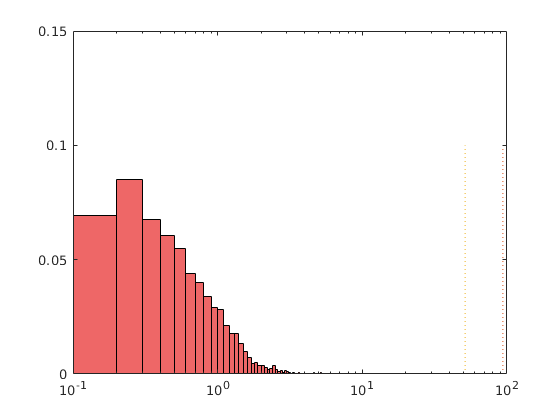

clf, hold off
histogram(f_score,Normalization="probability",FaceColor="#E20202")
set(gca, 'XScale', 'log')
xlim([10^-1,10^2])
ylim([0,0.15])
hold on
plot([93.56901091,93.56901091],[0,0.1],LineStyle=":")
plot([51.38983051,51.38983051],[0,0.1],LineStyle=":")
saveas(gcf, "fig4_dist.svg")

function Data = readPsico(file)
    opts = delimitedTextImportOptions("NumVariables", 31);
    opts.DataLines = [2, Inf];
    opts.Delimiter = ",";
    opts.VariableNames = ["Trial", "Class", "SelectedButton", "CorrectButton", "Hits", "AmpStim1", "FreqStim1", "AudStim1", "AmpStim2", "FreqStim2", "AudStim2", "AmpStim3", "FreqStim3", "AudStim3", "RelKD", "RelKU", "RelMov", "Luz", "TRW", "Set", "pd", "kd", "o1", "f1", "o2", "f2", "o3", "f3", "pu", "ku", "pb"];
    opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
    opts.ExtraColumnsRule = "ignore";
    opts.EmptyLineRule = "read";
    
    Data = readtable(file, opts);
end

function Fr = freq(D,pas,ven, mini, maxi)
    [xd, ~] = size(D);
    num = fix(ven/pas);
    tv = mini:pas:maxi;
    D = fix((D-mini)/pas)+1;
    Fr = zeros(xd,length(tv));
    for ens = 1 : xd
        for x = 1 : (length(tv)-num)
            B = (D(ens,:)>x-num & D(ens,:)<=x);
            suma = sum(B(:));
            Fr(ens,x+num) = suma/ven;
        end
    end
end

function El = which_el(Files,N)
    El = zeros(N,1);
    e = 0;
    a = 0;
    ename = 0;
    for f = 1:length(Files)
        if length(Files(f).name) > 9 && Files(f).name(8) == "e" && str2num(Files(f).name([2,3])) < 72
            if str2num(Files(f).name([2,3,7,9])) ~= ename
                e = e + 1;
                ename = str2num(Files(f).name([2,3,7,9]));
            end
            a = a + 1;
            El(a) = e;
        end
    end
end

function Fr = convo(D,pas,ven,mini,maxi,tipo)
    clf
    [xd, ~] = size(D);
    tv = mini:pas:maxi;
    Fr = zeros(xd,length(tv));
    if tipo==1
        con = @(c) sum(exp(-c.^2./(2*ven^2)),2,'omitnan')./(ven*sqrt(pi*2));
    elseif tipo==2
        con = @(c) 2*sum((c>=0).*exp(-c.^2./(2*ven^2)),2,'omitnan')./(ven*sqrt(pi*2));
    end
    for row =1:xd
        C = bsxfun(@minus,tv',D(row,:));
        Fr(row,:) = con(C);    
    end
end